clear;
addpath('C:\Users\johns\Documents\Github\QEM-MATLAB\RLC Circuit Models')

## Calculator for RLC Circuits

Rs = 10; %Ohms, from multiple sources
Ls = 15; %Inductance, in nH
Cs = 60; %Capacitancem in pH

Vstep = 1; %Voltage in V

## Graph Settings

t_start = 0; %start time in ns
t_stop = 16; %stop time in ns
t_res = 0.1; %resolution in ns
t_offset = 2; %number of ns to plot before
EnvLineWidth = 2;
NormLineWidth = 2;
NormStyle = ':';
%NormColor = 'r';

## Damping Envelope Settings

tol = 0.1; %Tolerance for underdamped solution

## Scaling

n = 10^-9; %scaling nano factor
p = 10^-12; %scaling pico factor
t_start = t_start*n;
t_stop = t_stop*n;
t_res = t_res*n;
t = linspace(t_start, t_stop, 2+(t_stop-t_start)/t_res);
R = Rs;
L = n*Ls;
C = p*Cs;

## Labeling

Rst = "R=" + num2str(Rs) + " Ohm ";
Cst = "C=" + num2str(Cs)+ "pF ";
Lst = "L=" + num2str(Ls) + "nH ";

thresh = 2*sqrt(L/C);
B = sqrt(((R/(2*L)))^2-1/(L*C));
 
i = i_RLC(R,L,C,t,Vstep);
v = v_RLC(R,L,C,t,Vstep);
%%Parameter sweep;



## Graphing

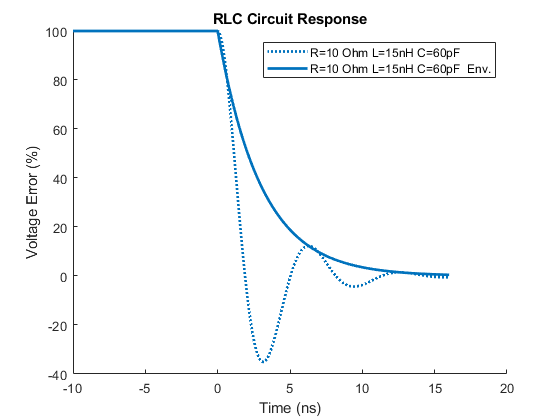

R=10 Ohm L=15nH C=60pF  Underdamped


hold all;
ln = plot([-t_offset, t*10^9],[Vstep,v]*100, 'DisplayName', Rst+Lst+Cst);
ln.LineWidth = NormLineWidth;
title('RLC Circuit Response');
xlabel('Time (ns)');
ylabel('Voltage Error (%)');
legend('-DynamicLegend');


if (R<thresh-thresh*tol)
    %Oscillating full solution plot style
    ln.LineStyle = NormStyle;

    color = get(ln, 'Color');
    B = sqrt(((R/(2*L)))^2-1/(L*C));
    disp(Rst+Lst+Cst +" Underdamped");
    v_env = -real(Vstep/(2*B*L*C)*(1/(-R/(2*L)+B)*exp(-R.*t/(2*L)+0*B.*t)- 1/(-R/(2*L)-B)*exp(-R.*t/(2*L)-0*B.*t)));
    ln2= plot([-10, t*10^9],[100, v_env*100], 'DisplayName', Rst+Lst+Cst+" Env.", 'Color', color);
    ln2.LineWidth = EnvLineWidth;
    hold on;

% end

## RLC Sweep (modify variable)

vstart = 15;
vinc = 20;
vstop = 55;

for Rs =vstart:vinc:vstop
    R = Rs;
    L = n*Ls;
    C = p*Cs;
    Rst = "R=" + num2str(Rs) + " Ohm ";
    Cst = "C=" + num2str(Cs)+ "pF ";
    Lst = "L=" + num2str(Ls) + "nH ";
    thresh = 2*sqrt(L/C);

    v = v_RLC(R,L,C,t,Vstep);
    ln = plot([-t_offset, t*10^9],[Vstep,v]*100, 'DisplayName', Rst+Lst+Cst);
    legend('-DynamicLegend');
    hold all;
    ln.LineWidth = NormLineWidth;
    color = get(ln, 'Color');

    if (R<thresh-thresh*tol)
        %Oscillating full solution plot style
        ln.LineStyle = NormStyle;
        %ln.Color = NormColor;

        %Envelope only solution (neglects osc)
        
        B = sqrt(((R/(2*L)))^2-1/(L*C));
        disp(Rst+Lst+Cst +" Underdamped");
        v_env = -real(Vstep/(2*B*L*C)*(1/(-R/(2*L)+B)*exp(-R.*t/(2*L)+0*B.*t)- 1/(-R/(2*L)-B)*exp(-R.*t/(2*L)-0*B.*t)));
        ln = plot([-t_offset, t*10^9],[100, v_env*100], 'DisplayName', Rst+Lst+Cst+" env.", 'Color', color);
        ln.LineWidth = EnvLineWidth;

    end
end